## Preparación del espacio de trabajo

clc;clear;close all;

### Carga de la imagen

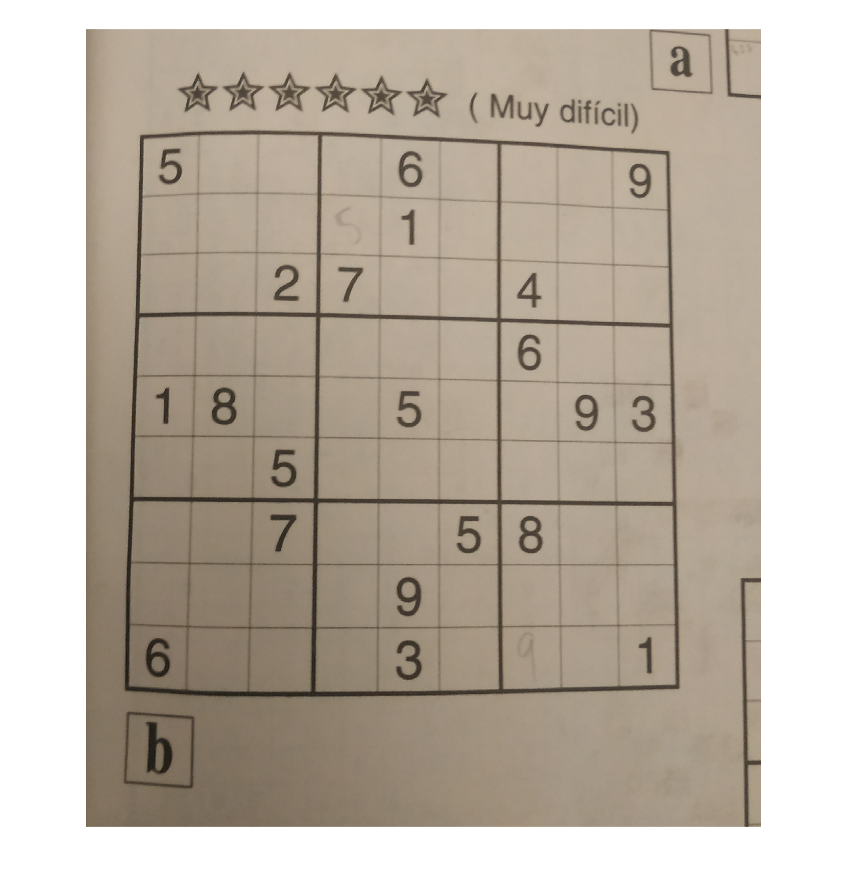

opt = "one";
if opt == "one"
    %% Carga de imagen.
    file = "sudokus\14.jpg";
    I = imread(file);
    imshow(I);
else
    fprintf('En la Image Adquisition Toolbox exporte la imagen al workspace con el nombre I.');
    f = helpdlg('En la Image Adquisition Toolbox exporte la imagen al workspace con el nombre I. Cuando haya acabado pulse `enter` sobre la ventana de comandos.');
    uiwait(f);
%     pause(5);
    imaqtool;
    pause();
    if(exist('I')==0 )
        fprintf('No ha guardado ninguna imagen o no se ha guardado en el formato correcto.');
        f = helpdlg('No ha guardado ninguna imagen o no se ha guardado en el formato correcto. Se cargará una de ejemplo.');
        uiwait(f);
        I = imread('sudokus\7.jpeg');
    elseif(length(size(I))==4)
        fprintf('Se ha guardado en la variable I un video, se tomara solo el primer frame del mismo.');
        f = helpdlg('Se ha guardado en la variable I un video, se tomara solo el primer frame del mismo.');
        uiwait(f);
        I = I(:,:,:,1);
    end
    imshow(I);    
end

### Procesado de la imagen

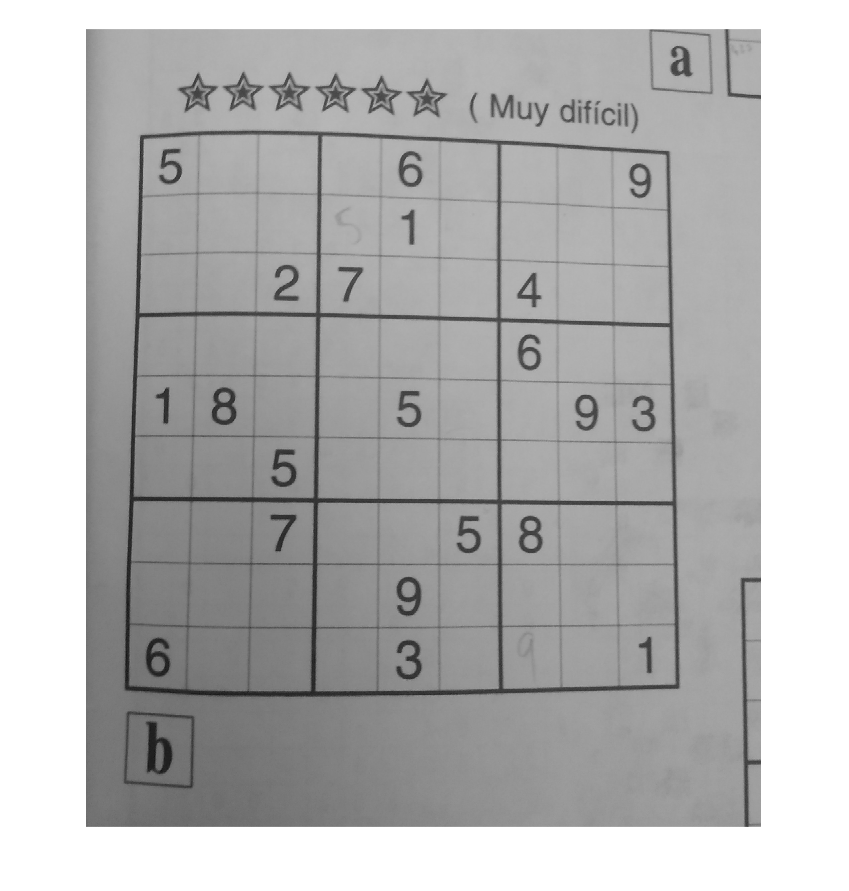

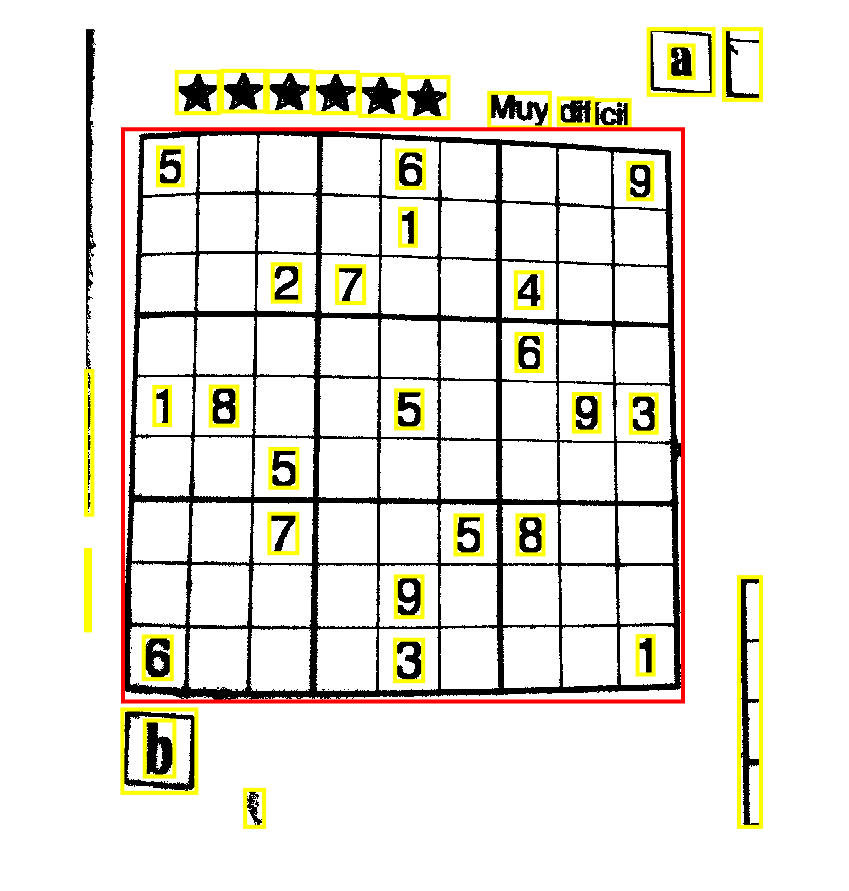

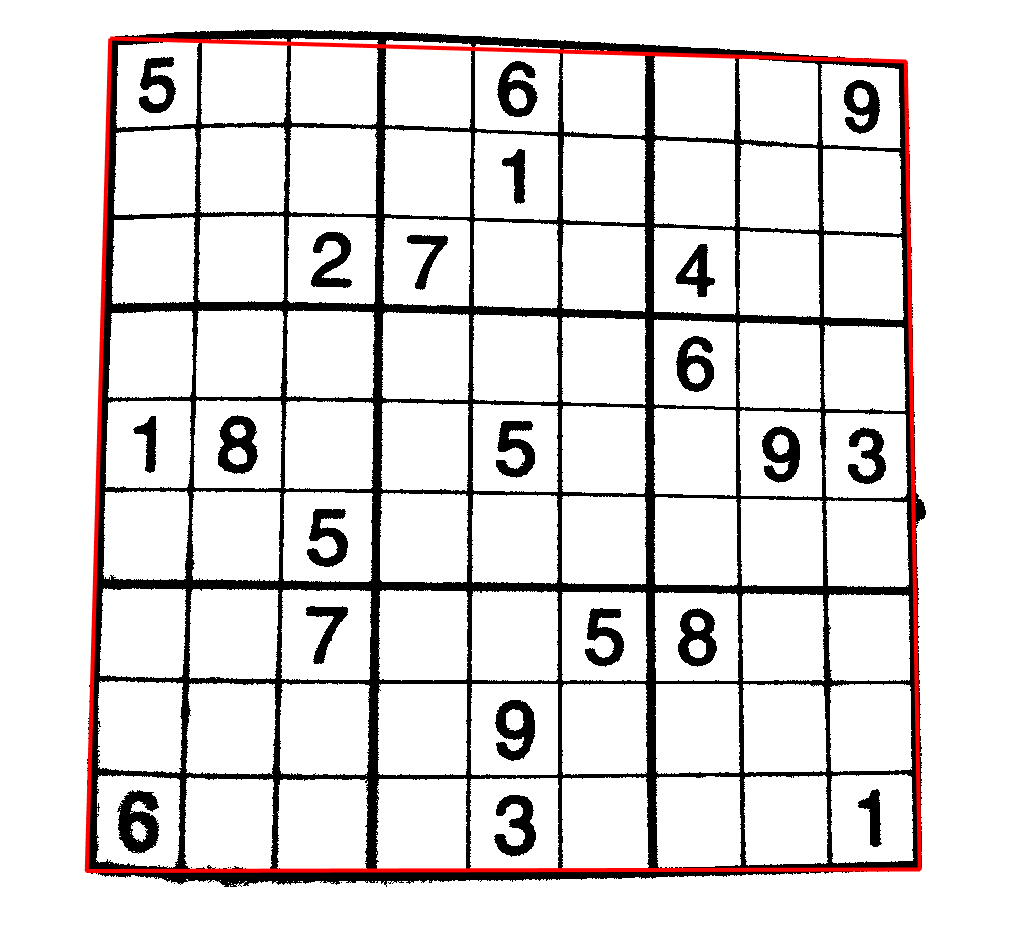

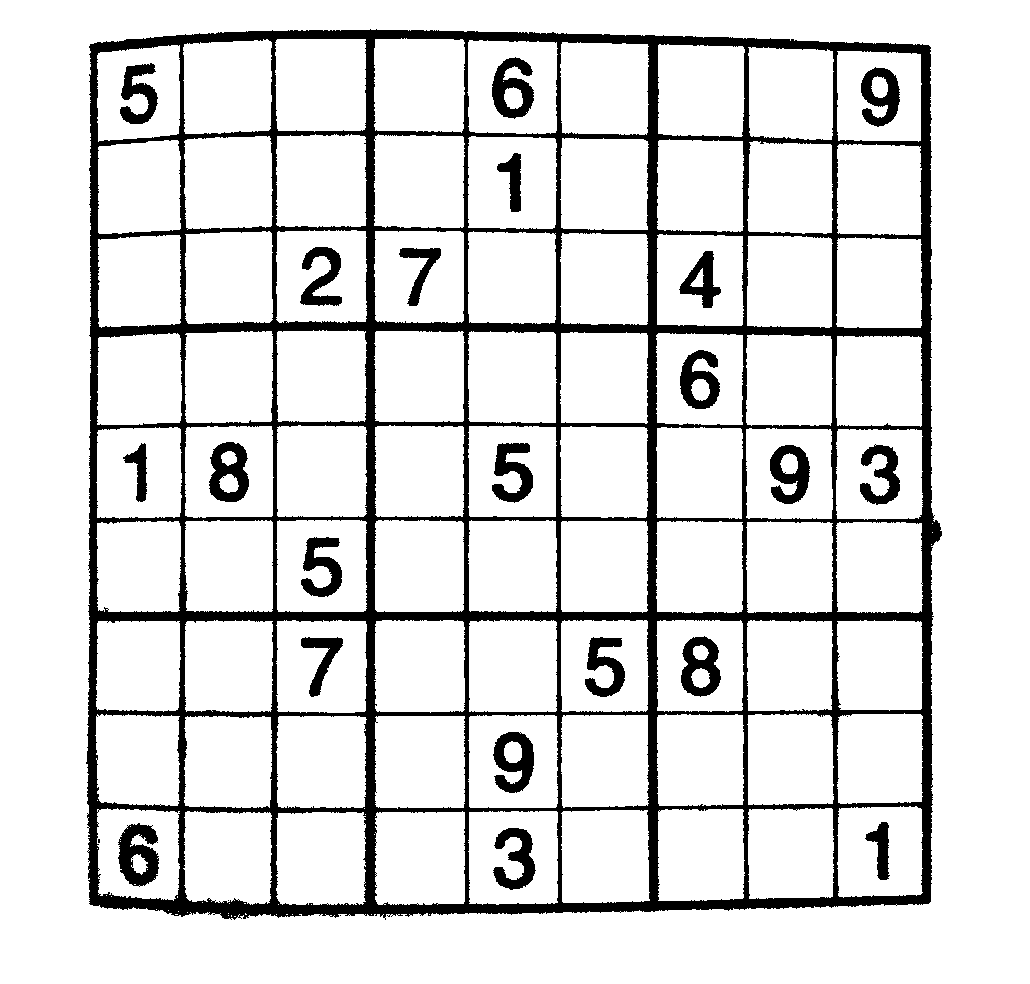

procesadoSudoku;

### Reconocimiento del sudoku   

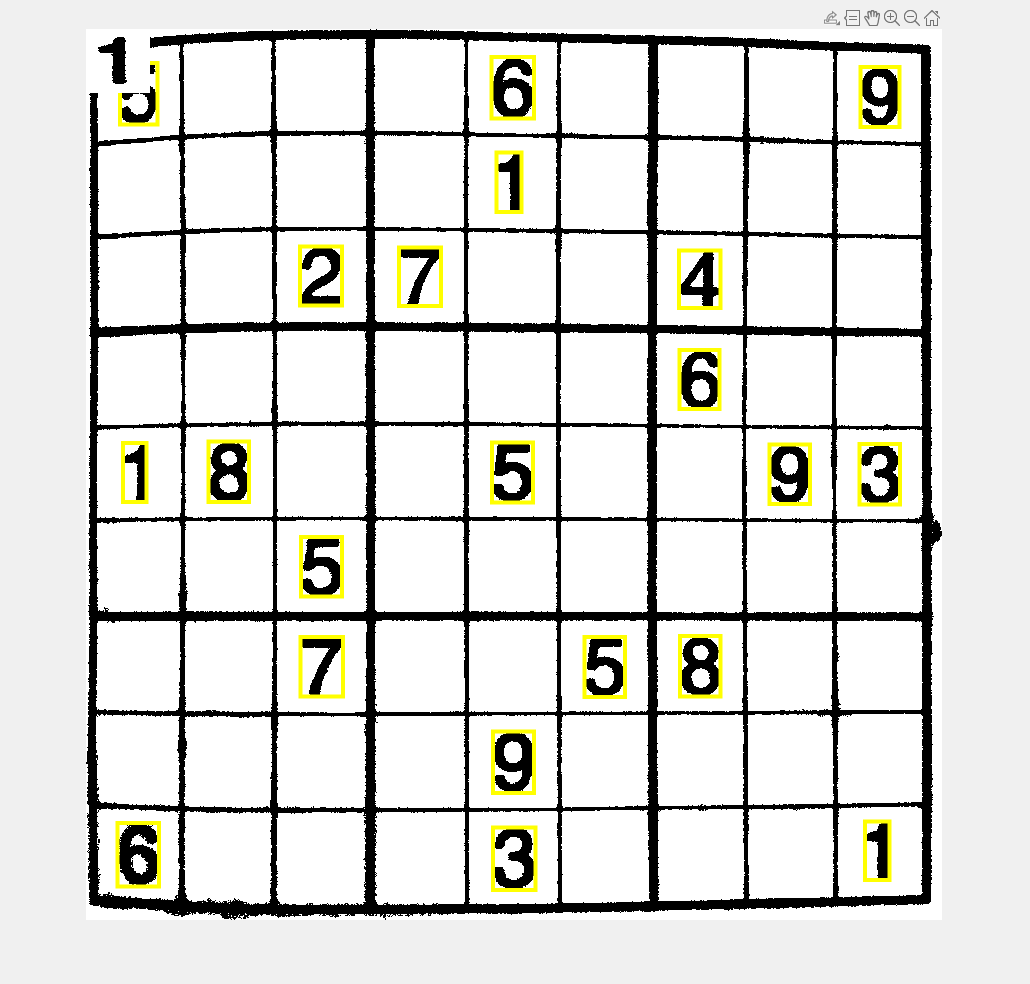

load red_entrenada.mat;

reconocimiento;

matriz

matriz =      5     0     0     0     6     0     0     0     9
     0     0     0     0     1     0     0     0     0
     0     0     2     7     0     0     4     0     0
     0     0     0     0     0     0     6     0     0
     1     8     0     0     5     0     0     9     3
     0     0     5     0     0     0     0     0     0
     0     0     7     0     0     5     8     0     0
     0     0     0     0     9     0     0     0     0
     6     0     0     0     3     0     0     0     1


### Resolucion del Sudoku.

SudokuResuelto =      5     7     3     2     6     4     1     8     9
     8     4     6     5     1     9     3     7     2
     9     1     2     7     8     3     4     6     5
     7     2     9     3     4     1     6     5     8
     1     8     4     6     5     2     7     9     3
     3     6     5     9     7     8     2     1     4
     4     9     7     1     2     5     8     3     6
     2     3     1     8     9     6     5     4     7
     6     5     8     4     3     7     9     2     1


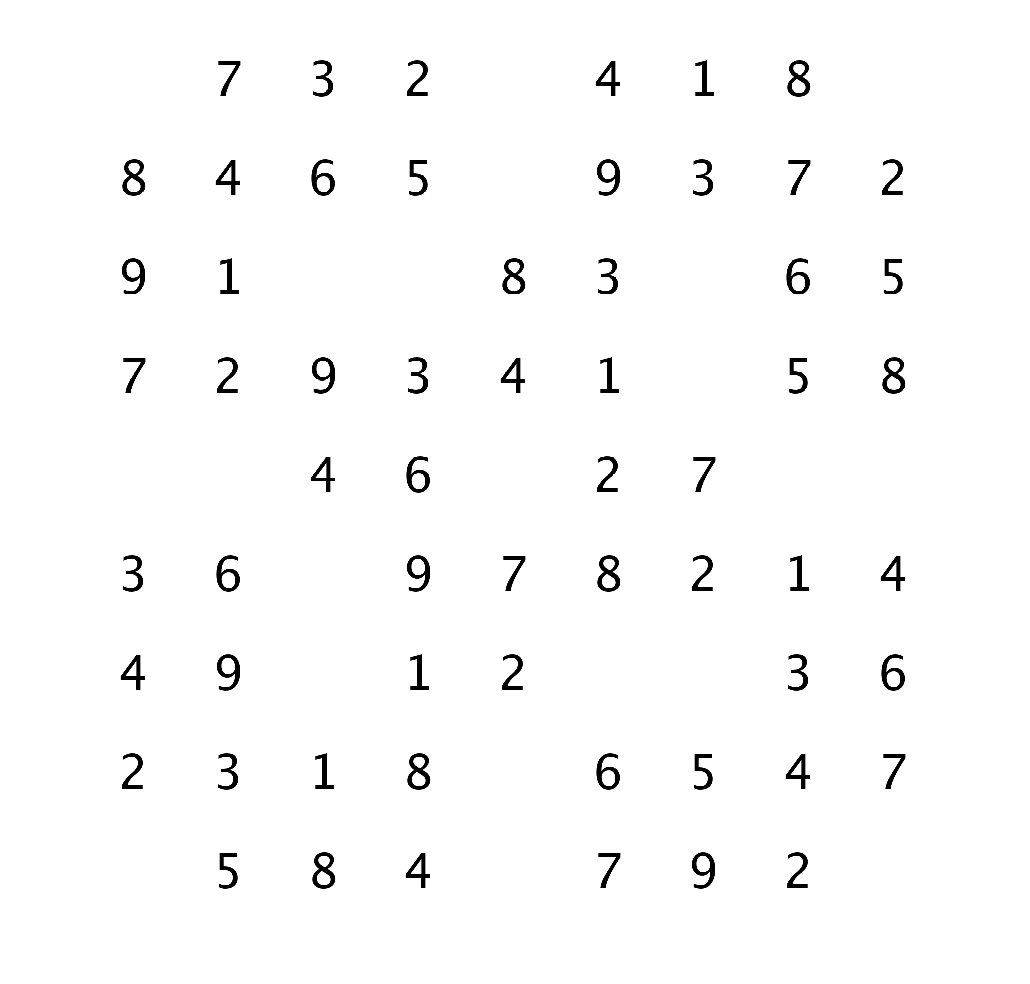

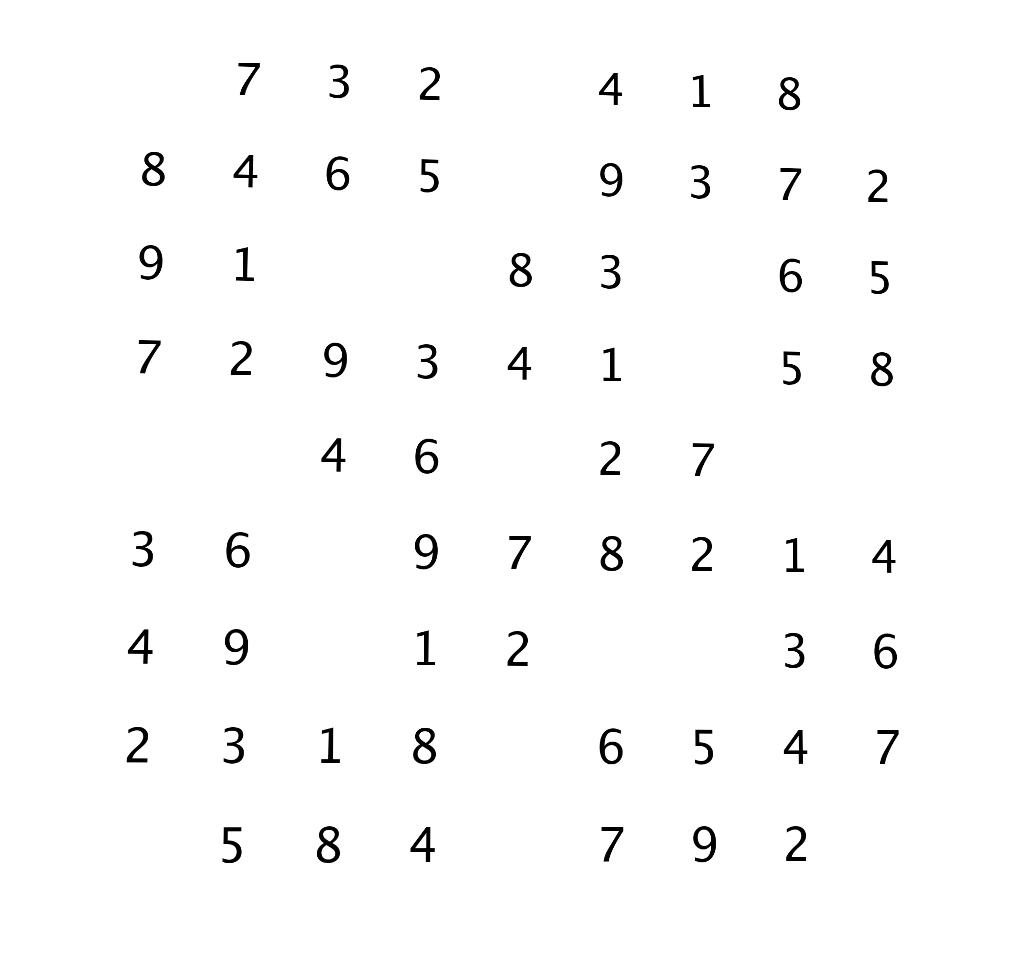

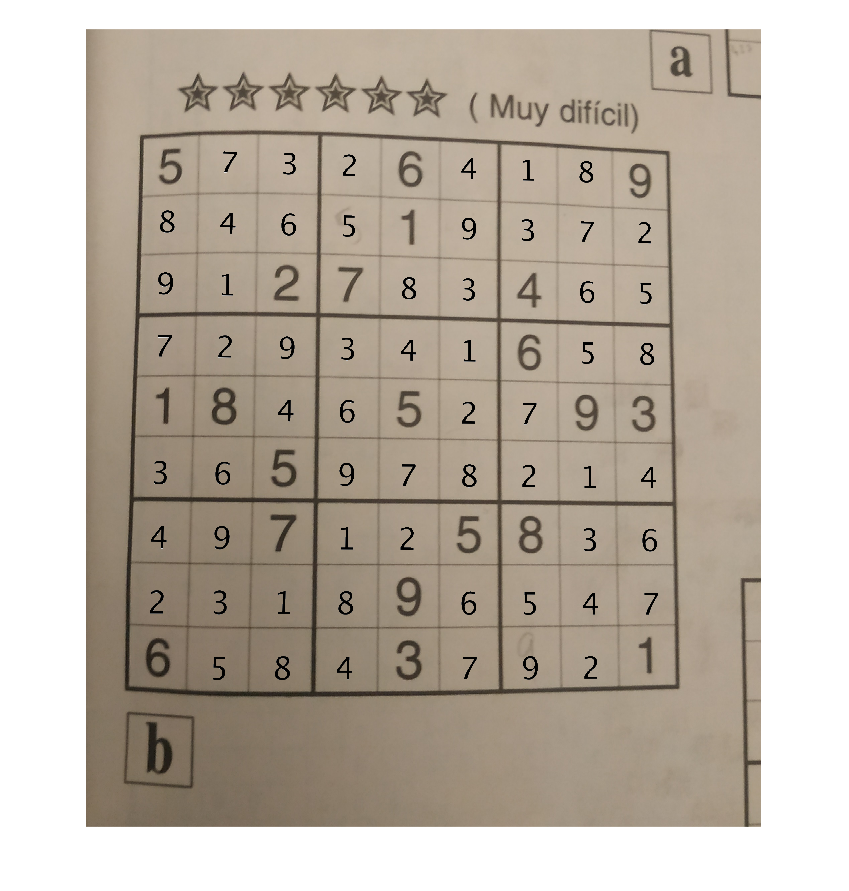

resoluble = comprobar_Sudoku(matriz);
if(resoluble)
    figure();
    SudokuResuelto = solver_pocho(matriz)
    imprimir_numeros;
else
    fprintf('No se puede resolver\n');
    helpdlg('El sudoku no se ha procesado correctamente o no tiene solución.');
end